**Giordano Dylan - Martelet Curtis                            M1 EEA Grp C**

# Rapport TP3: Filtrage sur Hacheur série/Hacheur entrelacés 2 voies

## Partie 1: Hacheur série simple

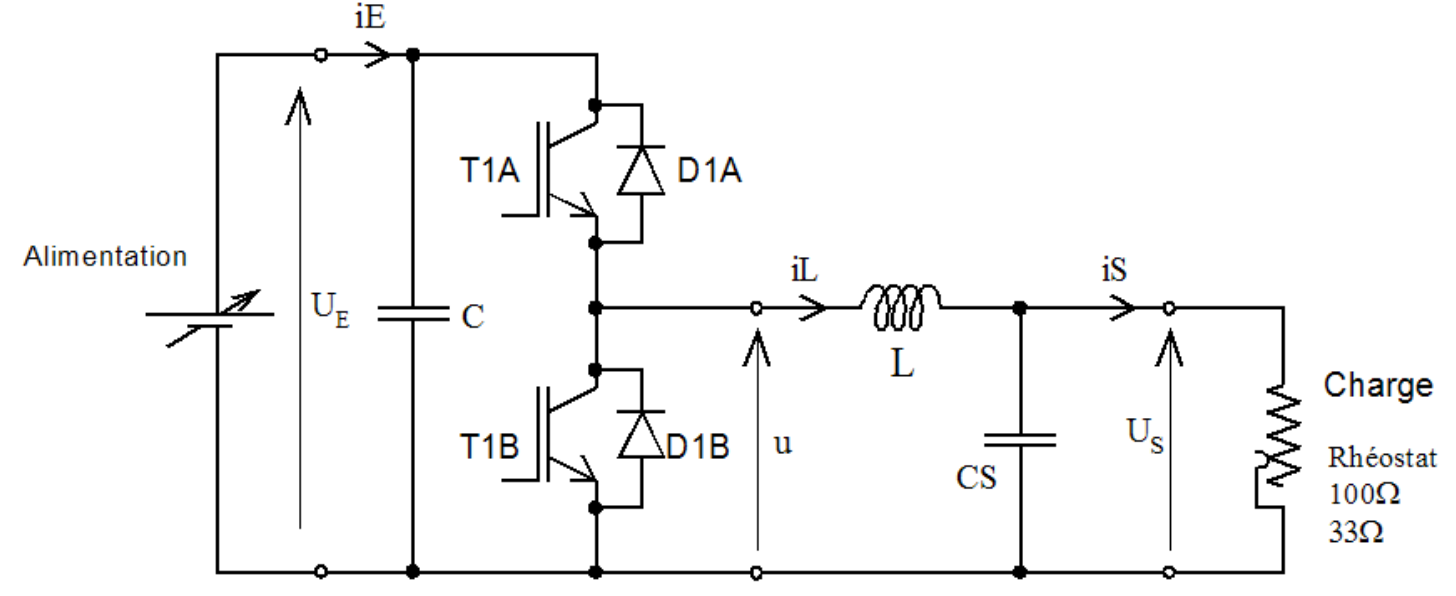

Résistance parasite: $R=\frac{U}{I}=\frac{0\ldotp 25}{2}=0\ldotp 125\Omega$.

Mesure de L: Nous mesurons le $\Delta I_L$ graces aux curseurs de l'oscilloscope : nous relevons 3.625A.

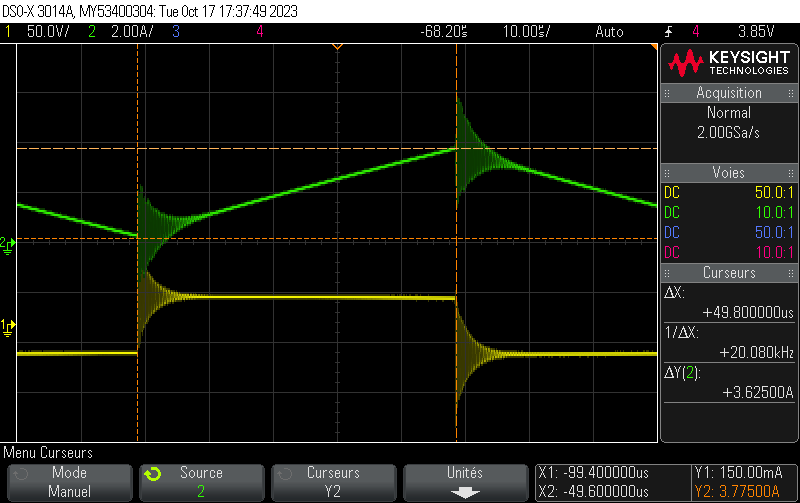

***Légende: Amplitude signal jaune: 55V***

***                Amplitude signal vert: 3.625A***


$$\Delta I_{L\;\textrm{Prattique}} =3,625A\;;V_{L\;\textrm{pratique}} =55V\;;F_{\textrm{dec}} =10\textrm{kHz}$$


On prend le rapport cyclique pour le cas le plus défavorable, c'est à dire 0.5 dans le cas du hacheur série simple.

On a $V_L =V_E$ pour $0<T<\alpha T$ : $V_L =\frac{L\times \Delta I_L }{\alpha T}\iff L=\frac{\alpha V_L }{\Delta I_L \times F_{\textrm{dec}} }=\frac{55\times 0,5}{3,625\times 10\textrm{e3}}=0,758\textrm{mH}$.


$$\Delta I_{L_{\max } } =\frac{\alpha V_E }{L\times F_{\textrm{dec}} }=\frac{55}{2\times 1e-3\times 10\textrm{e3}}=3\ldotp 627A$$


Expérimentalement, nous relevons une ondulation de courant égale à 3.625A. 

Pour le cas le plus défavorable, on prend $\alpha =0,5$.


$$\Delta V_s =\frac{\Delta I_L }{8\times C\times F_{\mathrm{dec}} }\iff C=\frac{\Delta I_L }{8\times \Delta V_C \times F_{\mathrm{dec}} }=\frac{3\ldotp 627}{8\times 1\ldotp 2\times 10\mathrm{e3}}=37\ldotp 7\mu F$$


De manière pratique, nous devons avoir un condensateur de sortie égal à $35\mu F$pour que l'ondulation de la tension de sortie soit égale à 1.2V.

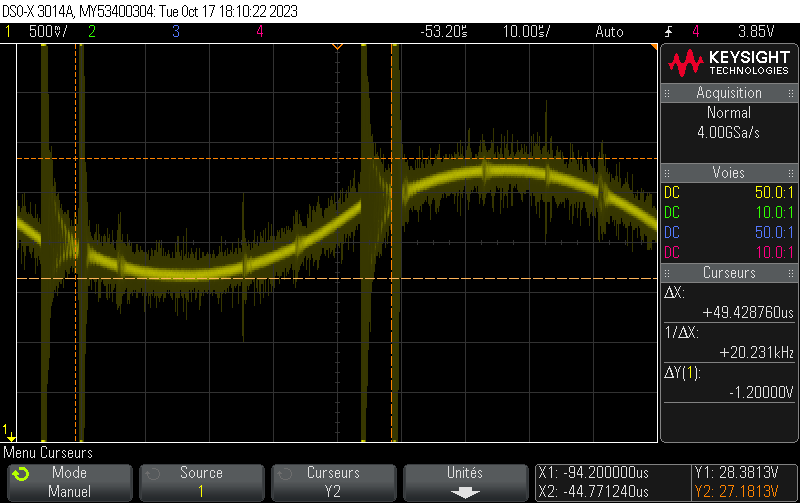

## Partie 2: Hacheurs série entrelacés

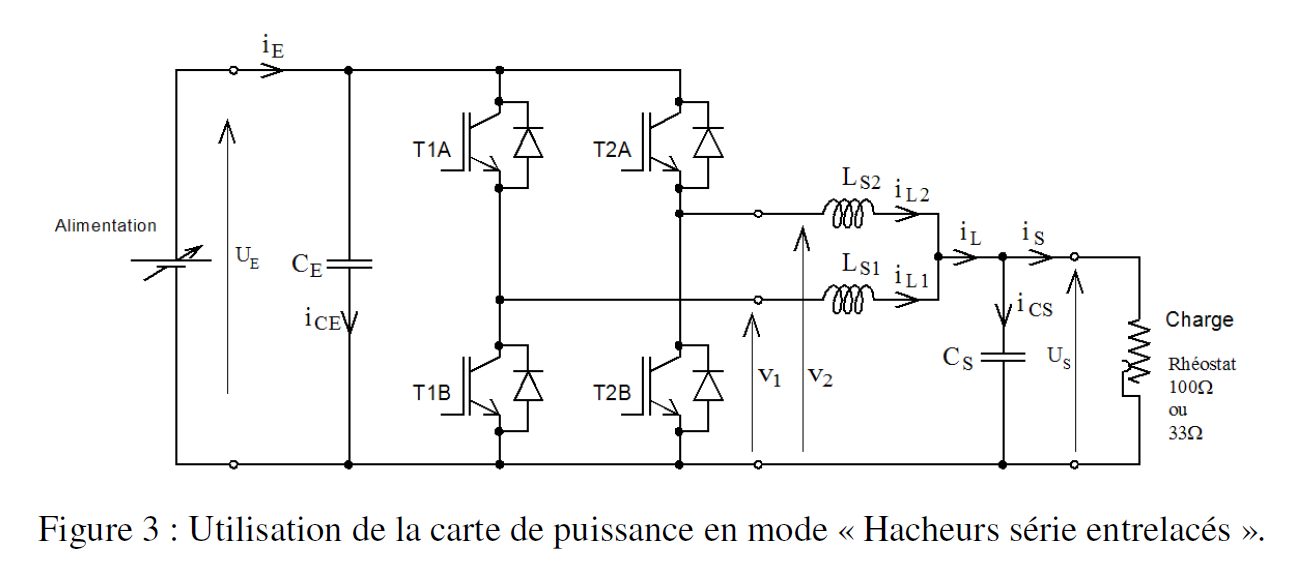

Résistance parasite : $R_{\mathrm{parasite}} =125m\Omega$. On a deux montage d'inductance en série, donc $R_{\mathrm{parasite}}^{\prime } =2\times R_{\mathrm{parasite}} =125\times 2=250m\Omega$.

L'inductance équivalente correspond à la mise en série de 2 bobines.:$L^{\prime } =2\times 470=940\mu H$

Pour le hacheur série classique : $W_{L_{\max } } =\frac{L\times {i_{L_{\max } } }^2 }{2}=\frac{0\ldotp 76e-3*{3\ldotp 775}^2 }{2}=0\ldotp 54\;\textrm{mW}$ & $W_{C_{\max } } =\frac{C\times {v_{C_{\max } } }^2 }{2}$=$\frac{35e-6*{27\ldotp 2}^2 }{2}=1\ldotp 3\mathrm{mW}$

Pour les hacheurs série entrelacés : $W_{L_{\max } } =\frac{L\times {i_{L_{\max } } }^2 }{2}=\frac{470e-6\times {\left(0\ldotp 507\right)}^2 }{2}=60\mu W$ & $W_{C_{\max } } =\frac{C\times {v_{C_{\max } } }^2 }{2}=\frac{2e-6\times {13}^2 }{2}=171\mu W$

# **Vérifier avec les valeurs des autres !!!**

Calcul de $\Delta$iLmax:

Pour un rapport cyclique de 0.25 : 


$$\Delta \mathrm{iLmax}=\frac{\mathrm{Ve}}{16\times L\times \mathrm{Fdec}}=\frac{60}{16\times 470e-6\times 10\mathrm{e3}}=0\ldotp 78A$$


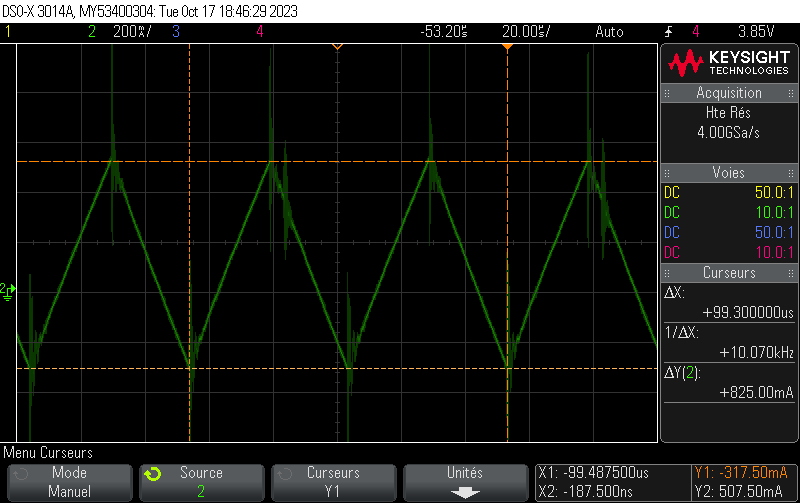

***Légende: Courbe Verte: ***$\Delta \textrm{iL}$***dans le cas d'un hacheur série entrelacée.***

Dans la pratique, nous mesurons un $\Delta \textrm{iL}$ de 0,825 A (voir capture). 

Ce qui est cohérent avec la valeur calculé. De plus nous remarquons que l'ondulation $\Delta \textrm{iL}$ dans le cas de l'entrelacé est divisé par 4 par rapport au hacheur simple. 

**Calcul de **$\Delta \textrm{Vsmax}$**:**


$$\Delta V_{s\;\max } =\frac{\Delta I_{\mathrm{Lmax}} }{8\times C\times F_{\mathrm{dec}} }=\frac{0\ldotp 825}{2\times 8\times 35e-6\times 10\mathrm{e3}}=147\mathrm{mV}$$


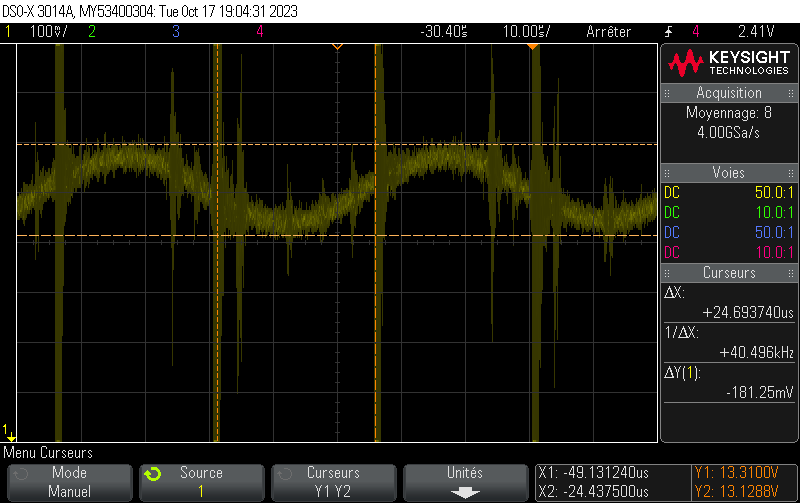

Dans la pratique, nous mesurons un ${\Delta \textrm{Vs}}_{\max }$ de 181,25 mV (voir capture). 

Ce qui est cohérent avec la valeur théorique calculé aux erreurs de mesures près lié au signal qui est très bruité. 

De plus nous remarquons que l'ondulation ${\Delta \textrm{Vs}}_{\max }$ dans le cas de l'entrelacé est divisé par 6 par rapport au hacheur simple. ($\left.{\Delta \textrm{Vs}}_{\max } =1,2V\right)$

### Comparaison entre les deux montages

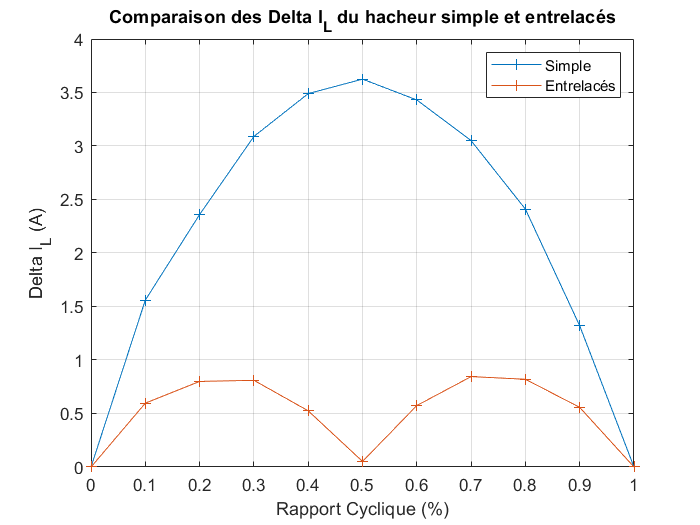

%Hacheur série
alpha=[0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
delta_iL=[0 1.56 2.36 3.09 3.49 3.625 3.43 3.05 2.41 1.32 0];
delta_Vs=[0 0.56 0.787 1.00 1.13 1.175 1.125 1.02 0.781 0.55 0];

%Hacheur série entrelacé:
delta_iL_e=[0 0.597 0.800 0.810 0.525 0.052 0.575 0.845 0.820 0.557 0];
delta_Vs_e=[0 0.128 0.152 0.146 0.091 0.030 0.125 0.147 0.143 0.091 0];


plot(alpha,delta_iL,'+-',alpha,delta_iL_e,'+-');
title('Comparaison des Delta I_L du hacheur simple et entrelacés')
xlabel('Rapport Cyclique (%)'); ylabel('Delta I_L (A)');legend("Simple","Entrelacés")
grid on

On peut observer que l'ondulation max de l'entrelacé est divisé par 4,5 par rapport aux hacheur simple.

De plus nous observons l'ondulation maximal pour 2 rapports cyclique différents ($\left.\alpha =0,25\;\textrm{et}\;\alpha =0,75\right)$

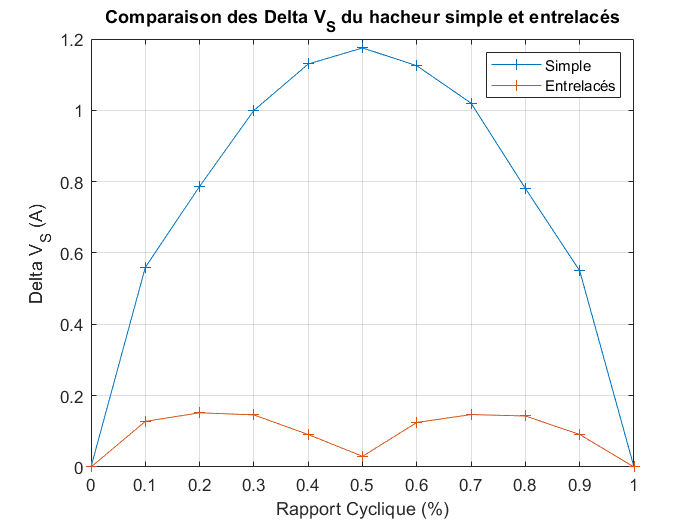

plot(alpha,delta_Vs,'+-',alpha,delta_Vs_e,'+-');
title('Comparaison des Delta V_S du hacheur simple et entrelacés')
xlabel('Rapport Cyclique (%)'); ylabel('Delta V_S (A)');legend("Simple","Entrelacés")
grid on

### **Calcul la nouvelle valeur de capacité (plus petite) permettant obtenir la même amplitude d’ondulation de tension de sortie que dans le cas du hacheur simple:**  


$$C=\frac{{\Delta \mathrm{iL}}_{\max } }{16\times \Delta \mathrm{Vs}\times \mathrm{Fdec}}=\frac{0,825}{16\times 1,2*10\mathrm{e3}}=4,29\mu F$$


Pour une fréquence de découpage de 10kHz. Pour obtenir une ondulation de tension de 1,2V, il nous faut une valeur de capacité de $4,29\mu F$.

En pratique nous avons mis une capacité de $5\mu F$ et nous mesurons une ondulation de 1V maximum.(Voir capture)

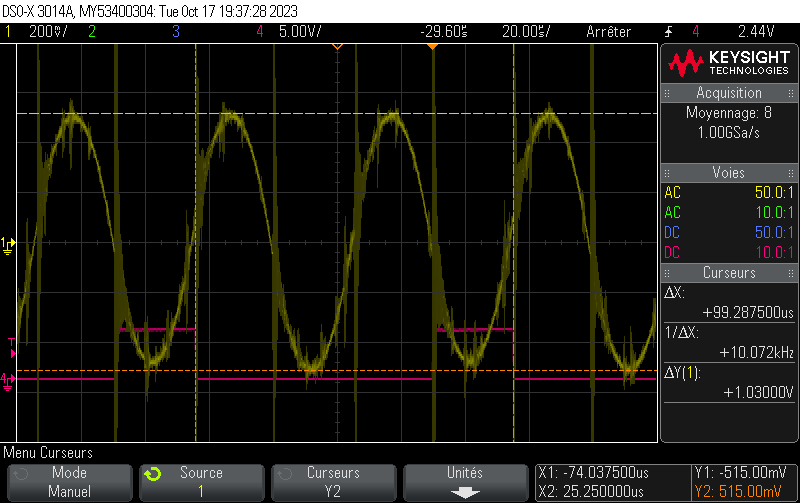

### **Calcul la nouvelle fréquence de découpage qui permet d’obtenir la même amplitude d’ondulation de tension de sortie que dans le cas du hacheur simple:**

En théorie, pour avoir une ondulation de $1\ldotp 2V$ avec une capacité de $37,7\mu F$ il nous faut un $\mathrm{Fdec}=\frac{{\Delta \mathrm{iL}}_{\max } }{16\times \Delta \mathrm{Vs}\times C}=\frac{0,825}{2\times 8\times 1,2\times 37,7e-6}=1,14\;k\mathrm{Hz}$

En pratique nous avons obtenons $1\ldotp 2V$ d'ondulation avec une capacité de $35\mu F$ et une fréquence de découpage de $3,36\mathrm{kHz}$.